clear;
close all; 

diam = 0.066; % in meters
r_prop = diam/2; % in meters
m_prop = 0.009/4; % in kg
dist_xy = 0.047625; % in meters
dist_r = sqrt(2*dist_xy^2); % in meters

I_body = m_prop*r_prop^2;
J_p = I_body + m_prop*dist_r^2; 
pt1 = [10400/60; 0.078]; 
pt2 = [29600/60; 0.092];
slope = (pt2(2)-pt1(2))/(pt2(1)-pt1(1));
b = pt2(2)-slope*pt2(1);
C_t = @(n) slope*n + b;
C_p = 0.041;


syms p_x p_x_dot p_y p_y_dot p_z p_z_dot phi phi_dot theta theta_dot psi psi_dot throttle aileron elevator rudder m g J_xx J_yy J_zz J_p n1 n2 n3 n4 rho

x1dot = p_x_dot;
x2dot = (cos(phi)*sin(theta)*cos(psi) + sin(phi)*sin(psi))*(throttle/m)

$$x2dot = \frac{\mathrm{throttle}\,\left(\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\right)}{m}$$

x3dot = p_y_dot;
x4dot = (cos(phi)*sin(theta)*sin(psi) - sin(phi)*cos(psi))*(throttle/m)

$$x4dot = -\frac{\mathrm{throttle}\,\left(\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right)}{m}$$

x5dot = p_z_dot;    
x6dot = g - (cos(phi)*cos(theta))*throttle/m

$$x6dot = g-\frac{\mathrm{throttle}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)}{m}$$

J = [J_xx 0 0; 0 J_yy 0; 0 0 J_zz];
x7dot = phi_dot;
x8dot = (J_yy-J_xx)/J_xx*theta_dot*psi_dot + 2*pi*J_p/J_xx*theta_dot*(n1-n2+n3-n4) + aileron/J_xx

$$x8dot = \frac{\mathrm{aileron}}{J_{\mathrm{xx}}}-\frac{\dot{\psi }\,\dot{\theta }\,\left(J_{\mathrm{xx}}-J_{\mathrm{yy}}\right)}{J_{\mathrm{xx}}}+\frac{2\,\pi \,J_{p}\,\dot{\theta }\,\left(n_{1}-n_{2}+n_{3}-n_{4}\right)}{J_{\mathrm{xx}}}$$

x9dot = theta_dot;  
x10dot = (J_zz - J_xx)/J_yy*theta_dot*psi_dot + 2*pi*J_p/J_yy*phi_dot*(n1-n2+n3-n4) + elevator/J_yy

$$x10dot = \frac{\mathrm{elevator}}{J_{\mathrm{yy}}}-\frac{\dot{\psi }\,\dot{\theta }\,\left(J_{\mathrm{xx}}-J_{\mathrm{zz}}\right)}{J_{\mathrm{yy}}}+\frac{2\,\pi \,J_{p}\,\dot{\varphi }\,\left(n_{1}-n_{2}+n_{3}-n_{4}\right)}{J_{\mathrm{yy}}}$$

x11dot = psi_dot;
x12dot = (J_xx-J_yy)/J_zz*phi_dot*theta_dot + rudder/J_zz

$$x12dot = \frac{\mathrm{rudder}}{J_{\mathrm{zz}}}+\frac{\dot{\varphi }\,\dot{\theta }\,\left(J_{\mathrm{xx}}-J_{\mathrm{yy}}\right)}{J_{\mathrm{zz}}}$$

u = [n1; n2; n3; n4];
W = [throttle; aileron; elevator; rudder];
f = [x1dot; x2dot; x3dot; x4dot; x5dot; x6dot; x7dot; x8dot; x9dot; x10dot; x11dot; x12dot];
x = [p_x; p_x_dot; p_y; p_y_dot; p_z; p_z_dot; phi; phi_dot; theta; theta_dot; psi; psi_dot];

f_x = jacobian(f,x);
f_u = jacobian(f,W);


g = 9.8; % m/s^2
m = 0.068; % kg
J_xx = 0.69*10^-4; % kg*m^2
J_yy = 0.775*10^-4; % kg*m^2
J_zz = 1.5*10^-4; % kg*m^2
J_p = I_body + m_prop*dist_r^2;
rho = 1.293; % kg/m^3

n_eq = fzero(@(n)4*(C_t(n)*rho*diam^4*n^2)-m*g,200);
a_eq = C_t(n_eq)*rho*diam^4;
b_eq = C_t(n_eq)*rho*diam^4*dist_xy;
d_eq = C_p*rho*diam^5/(2*pi);

throttle = C_t(n1)*rho*diam^4*n1^2 + C_t(n2)*rho*diam^4*n2^2 + C_t(n3)*rho*diam^4*n3^2 + C_t(n4)*rho*diam^4*n4^2;
aileron = C_t(n1)*rho*diam^4*n1^2*dist_xy - C_t(n2)*rho*diam^4*n2^2*dist_xy - C_t(n3)*rho*diam^4*n3^2*dist_xy + C_t(n4)*rho*diam^4*n4^2

$$aileron = \frac{381\,{n_{1}}^{2}\,\left(\frac{11688041574397248936486922378915581\,n_{1}}{10889035741470030830827987437816582766592000}+\frac{203962077269861405053}{118059162071741130342400000}\right)}{8000}-\frac{381\,{n_{2}}^{2}\,\left(\frac{11688041574397248936486922378915581\,n_{2}}{10889035741470030830827987437816582766592000}+\frac{203962077269861405053}{118059162071741130342400000}\right)}{8000}-\frac{381\,{n_{3}}^{2}\,\left(\frac{11688041574397248936486922378915581\,n_{3}}{10889035741470030830827987437816582766592000}+\frac{203962077269861405053}{118059162071741130342400000}\right)}{8000}+{n_{4}}^{2}\,\left(\frac{11688041574397248936486922378915581\,n_{4}}{10889035741470030830827987437816582766592000}+\frac{203962077269861405053}{118059162071741130342400000}\right)$$

elevator = C_t(n1)*rho*diam^4*n1^2*dist_xy + C_t(n2)*rho*diam^4*n2^2*dist_xy - C_t(n3)*rho*diam^4*n3^2*dist_xy - C_t(n4)*rho*diam^4*n4^2;
rudder = -C_p*rho*diam^5*n1^2/(2*pi) + C_p*rho*diam^5*n2^2/(2*pi) - C_t(n3)*rho*diam^4*n3^2*dist_xy + C_t(n4)*rho*diam^4*n4^2;
% u_w = jacobian([throttle;aileron;elevator;rudder],[n1 n2 n3 n4]);
% f_w = f_u*u_w;


A_1 = subs(f_x,x,zeros(12,1));
A_2 = subs(A_1);
A_3 = subs(A_2,[n1 n2 n3 n4],[n_eq n_eq n_eq n_eq]);
A_4 = subs(A_3,W,[a_eq;0;0;0]);
A = double(subs(A_4,rho,1.293))

A =          0    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0    9.8000         0         0         0
         0         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0         0   -9.8000         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0        


B_1 = subs(f_u,x,zeros(12,1));
B_2 = subs(B_1);
B_3 = subs(B_2,[n1 n2 n3 n4],[n_eq n_eq n_eq n_eq]);
B = double(subs(B_3,W,[a_eq;0;0;0]))

B = 	1.0e+04 *

         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
   -0.0015         0         0         0
         0         0         0         0
         0    1.4493         0         0
         0         0         0         0
         0         0    1.2903         0


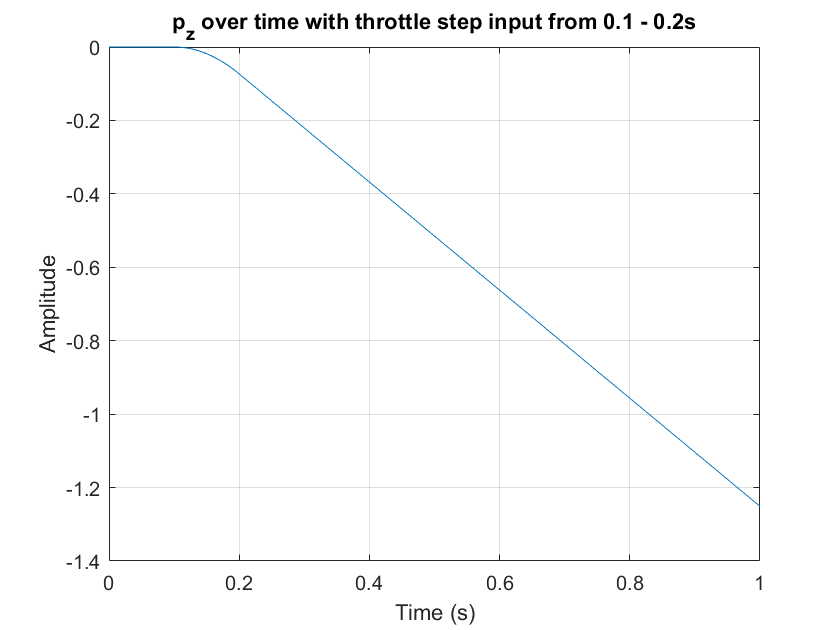


t = linspace(0,1,1000);
C = zeros(1,12);
D = [];
sys = ss(A,B,C,D);
u = zeros(4,numel(t));
u(1, (t>=0.1 & t<=0.2)) = 1;
% u(1,100) = 1;
% u(1,200) = -1;
[y,tOut,x_sim] = lsim(sys,u,t);

figure;
plot(t,x_sim(:,5));
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('p_z over time with throttle step input from 0.1 - 0.2s');

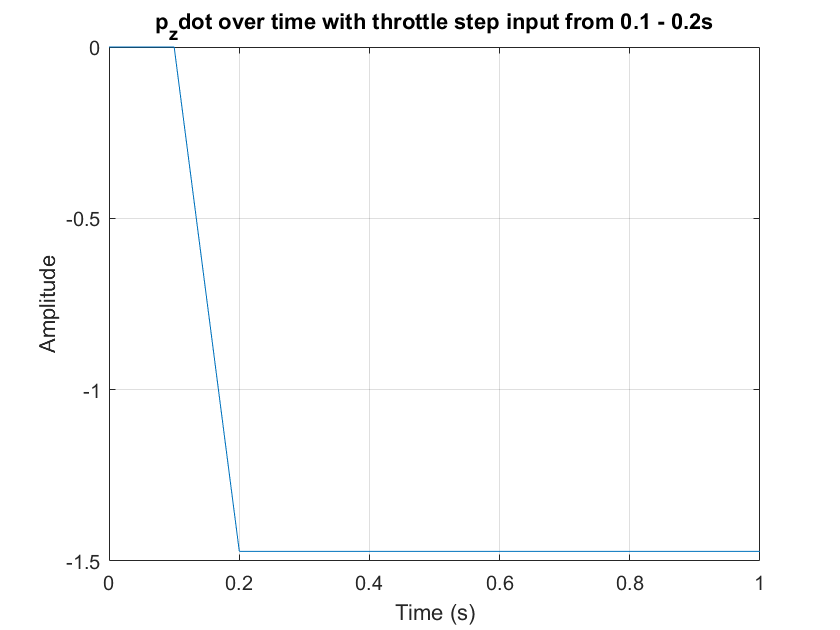


figure;
plot(t,x_sim(:,6));
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('p_zdot over time with throttle step input from 0.1 - 0.2s');

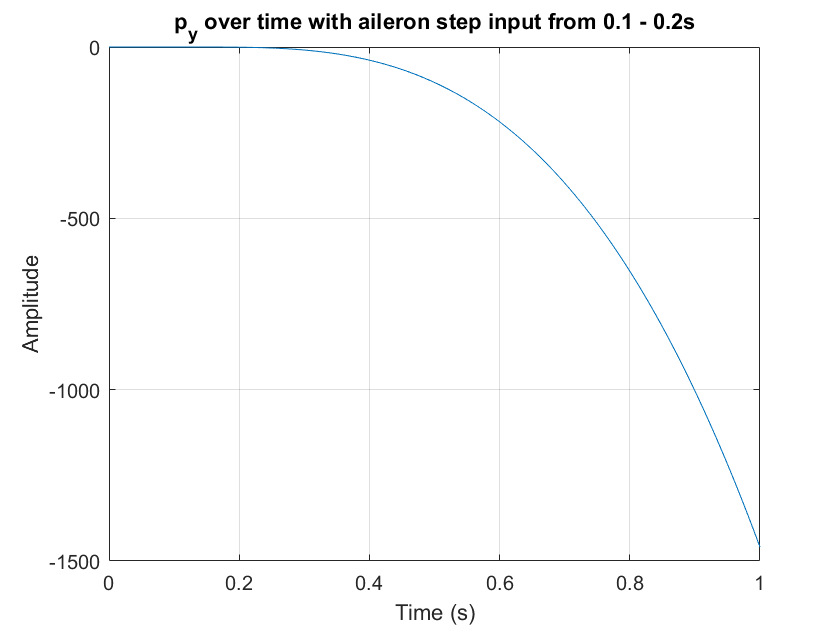

t = linspace(0,1,1000);
C = zeros(1,12);
D = [];
sys = ss(A,B,C,D);
u = zeros(4,numel(t));
u(2, (t>=0.1 & t<=0.2)) = 1;
[y,tOut,x_sim2] = lsim(sys,u,t);

figure;
plot(t,x_sim2(:,3));
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('p_y over time with aileron step input from 0.1 - 0.2s');

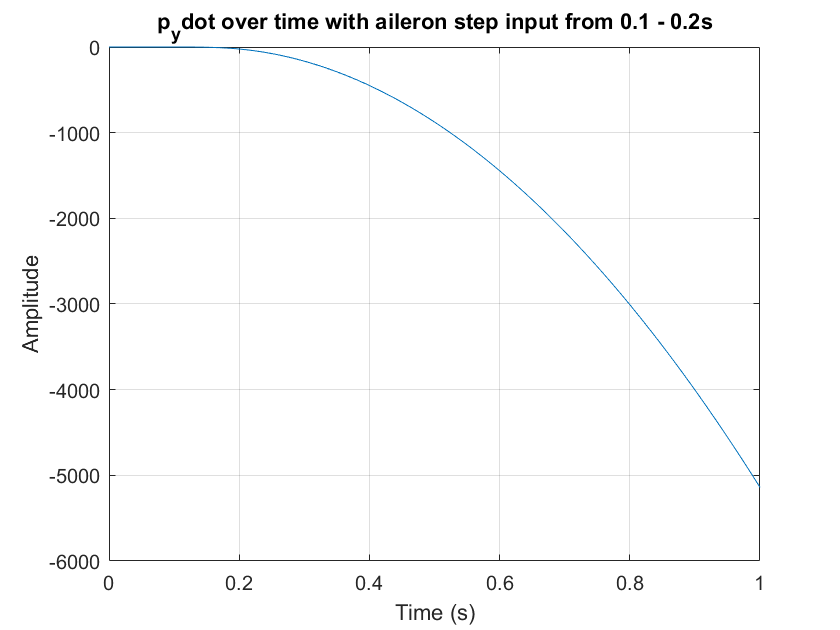


figure;
plot(t,x_sim2(:,4));
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('p_ydot over time with aileron step input from 0.1 - 0.2s');

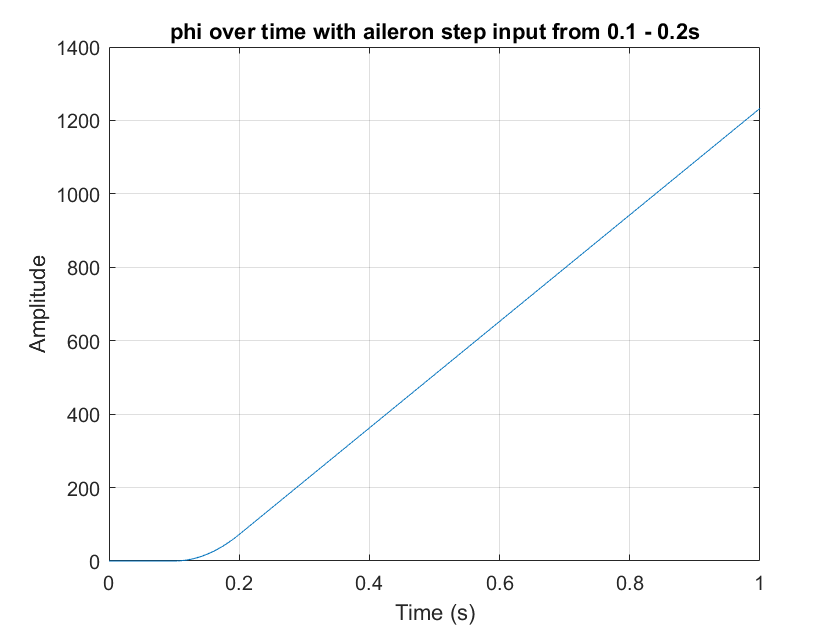


figure;
plot(t,x_sim2(:,7));
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('phi over time with aileron step input from 0.1 - 0.2s');

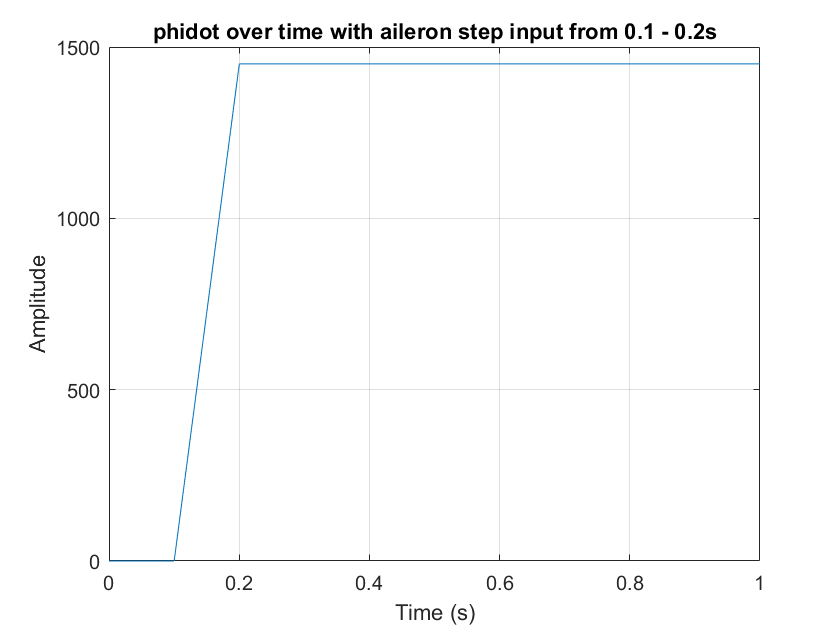


figure;
plot(t,x_sim2(:,8));
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('phidot over time with aileron step input from 0.1 - 0.2s');

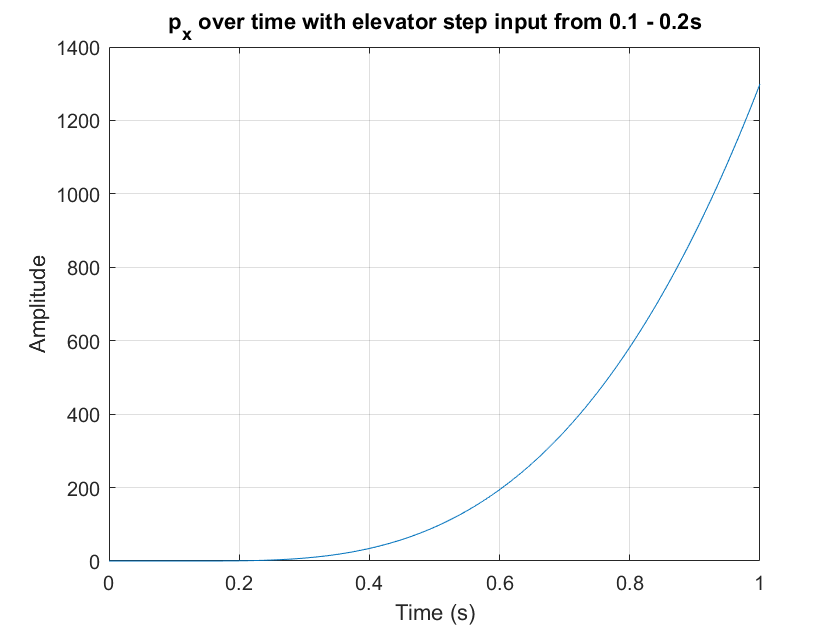

t = linspace(0,1,1000);
C = zeros(1,12);
D = [];
sys = ss(A,B,C,D);
u = zeros(4,numel(t));
u(3, (t>=0.1 & t<=0.2)) = 1;
[y,tOut,x_sim] = lsim(sys,u,t);

figure;
plot(t,x_sim(:,1));
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('p_x over time with elevator step input from 0.1 - 0.2s');

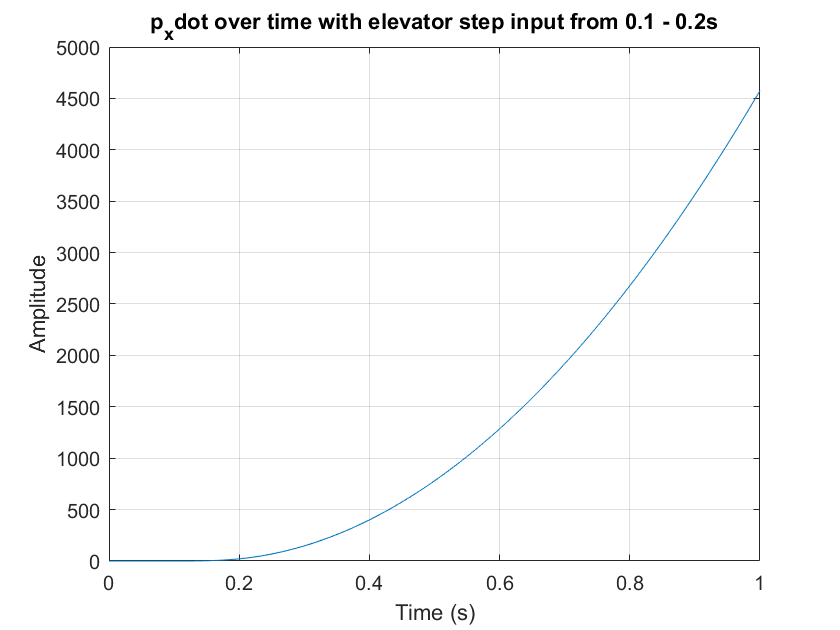


figure;
plot(t,x_sim(:,2));
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('p_xdot over time with elevator step input from 0.1 - 0.2s');

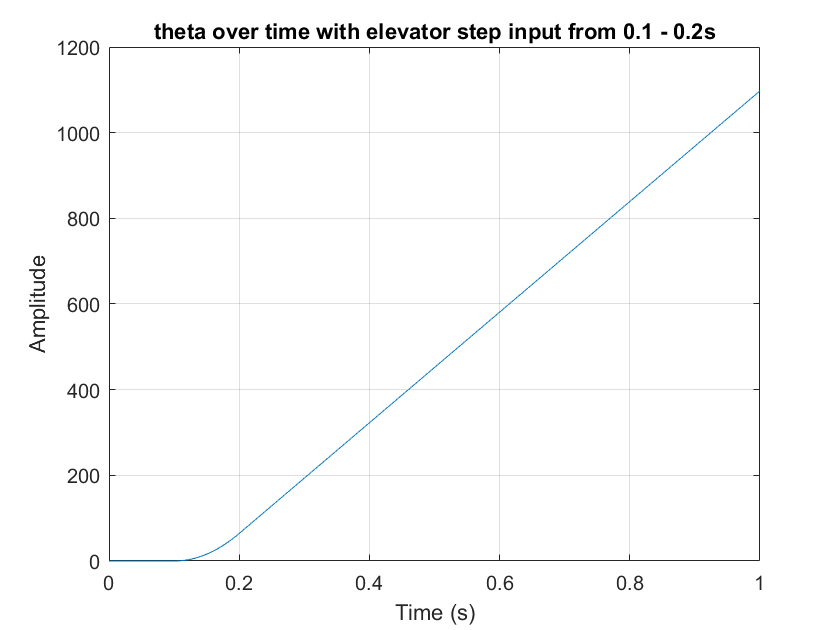



figure;
plot(t,x_sim(:,9));
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('theta over time with elevator step input from 0.1 - 0.2s');

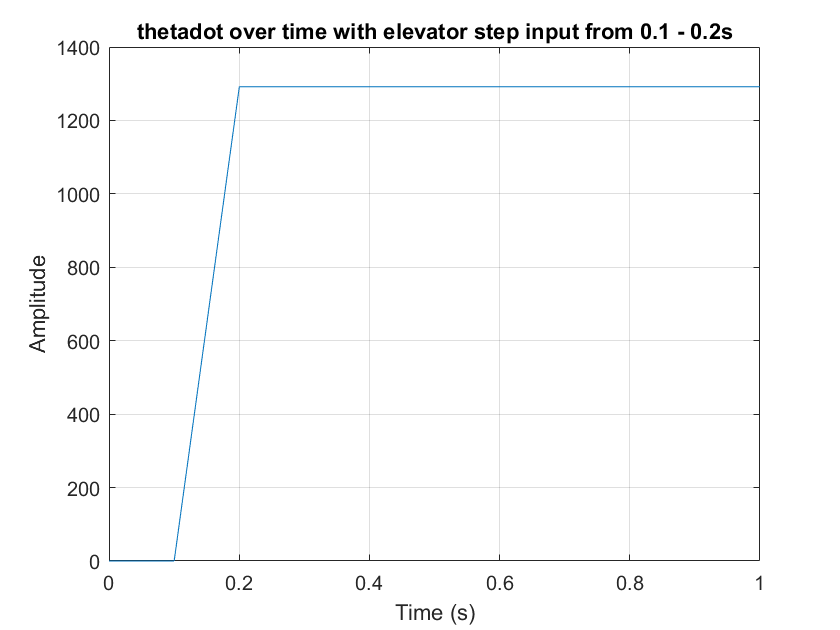


figure;
plot(t,x_sim(:,10));
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('thetadot over time with elevator step input from 0.1 - 0.2s');

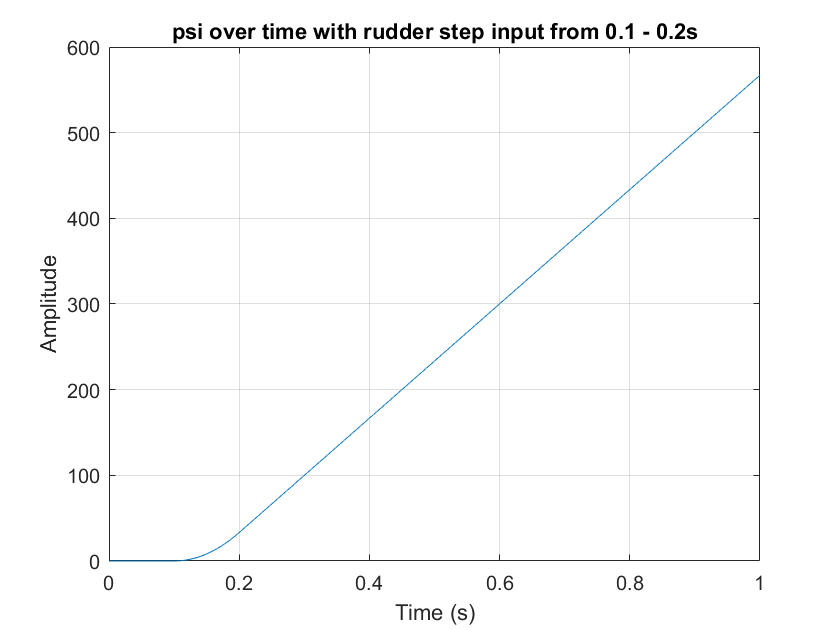

t = linspace(0,1,1000);
C = zeros(1,12);
D = [];
sys = ss(A,B,C,D);
u = zeros(4,numel(t));
u(4, (t>=0.1 & t<=0.2)) = 1;
[y,tOut,x_sim] = lsim(sys,u,t);

figure;
plot(t,x_sim(:,11));
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('psi over time with rudder step input from 0.1 - 0.2s');

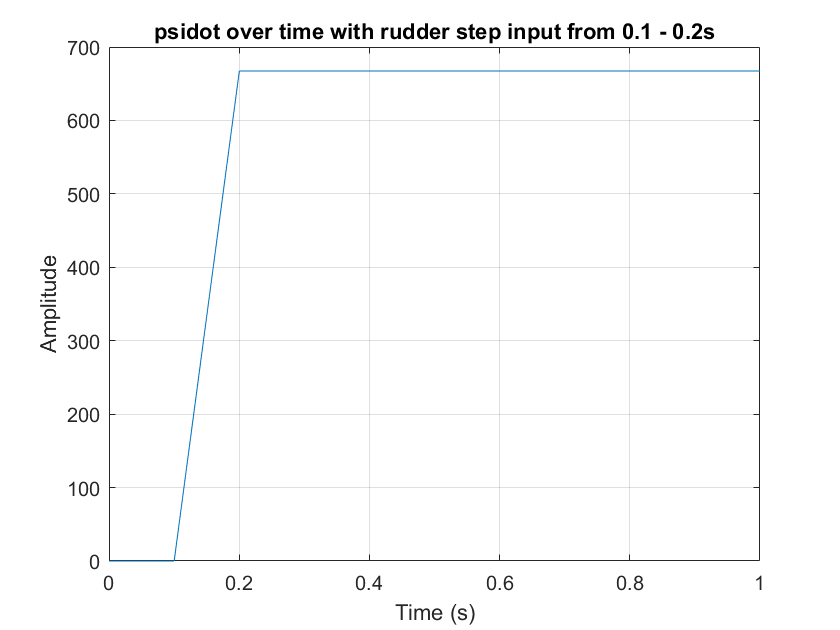


figure;
plot(t,x_sim(:,12));
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('psidot over time with rudder step input from 0.1 - 0.2s');